# Exam April 1, 2016

## Exercise 1 (Only exercise)

close all, clear
syms q1 q2 l1 l2

%q = [q1, q2]
q = sym('q', [1,2])

$$q = \left(\begin{array}{cc} q_{1} & q_{2} \end{array}\right)$$


dh = [l1 0 0 q(1);
      l2 0 0 q(2)];
l = [1 , 0.5];
dh = subs(dh,[l1 l2],l)

$$dh = \left(\begin{array}{cccc} 1 & 0 & 0 & q_{1}\\ \frac{1}{2} & 0 & 0 & q_{2} \end{array}\right)$$


T = getTranslationMatrix(dh)

$$T = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & 0 & \frac{\cos\left(q_{1}+q_{2}\right)}{2}+\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & 0 & \frac{\sin\left(q_{1}+q_{2}\right)}{2}+\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


P = T(1:2,4)

$$P = \left(\begin{array}{c} \frac{\cos\left(q_{1}+q_{2}\right)}{2}+\cos\left(q_{1}\right)\\ \frac{\sin\left(q_{1}+q_{2}\right)}{2}+\sin\left(q_{1}\right) \end{array}\right)$$


Pin = [0.4,1.2].'

Pin =     0.4000
    1.2000


Pfin = [-1,-0.2].'

Pfin =    -1.0000
   -0.2000


[qin1, qin2] = solve(P == Pin,q);

%Pick the solution with positive q2. That is the second one.
qin = [eval(qin1(2)), eval(qin2(2))]

qin =     0.8697    1.2132


rad2deg(qin)

ans =    49.8320   69.5127


%Pick the solution with positive q2. That is the second one again.
[qfin1, qfin2] = solve(P == Pfin,q);
qfin = [eval(qfin1(2)), eval(qfin2(2))]

qfin =     2.8391    1.7824


rad2deg(qfin)

ans =   162.6665  102.1224


deltaq= qfin - qin

deltaq =     1.9693    0.5691


%To calculate the trajectory

Tstar = 3.6926

Tstar = 3.6926

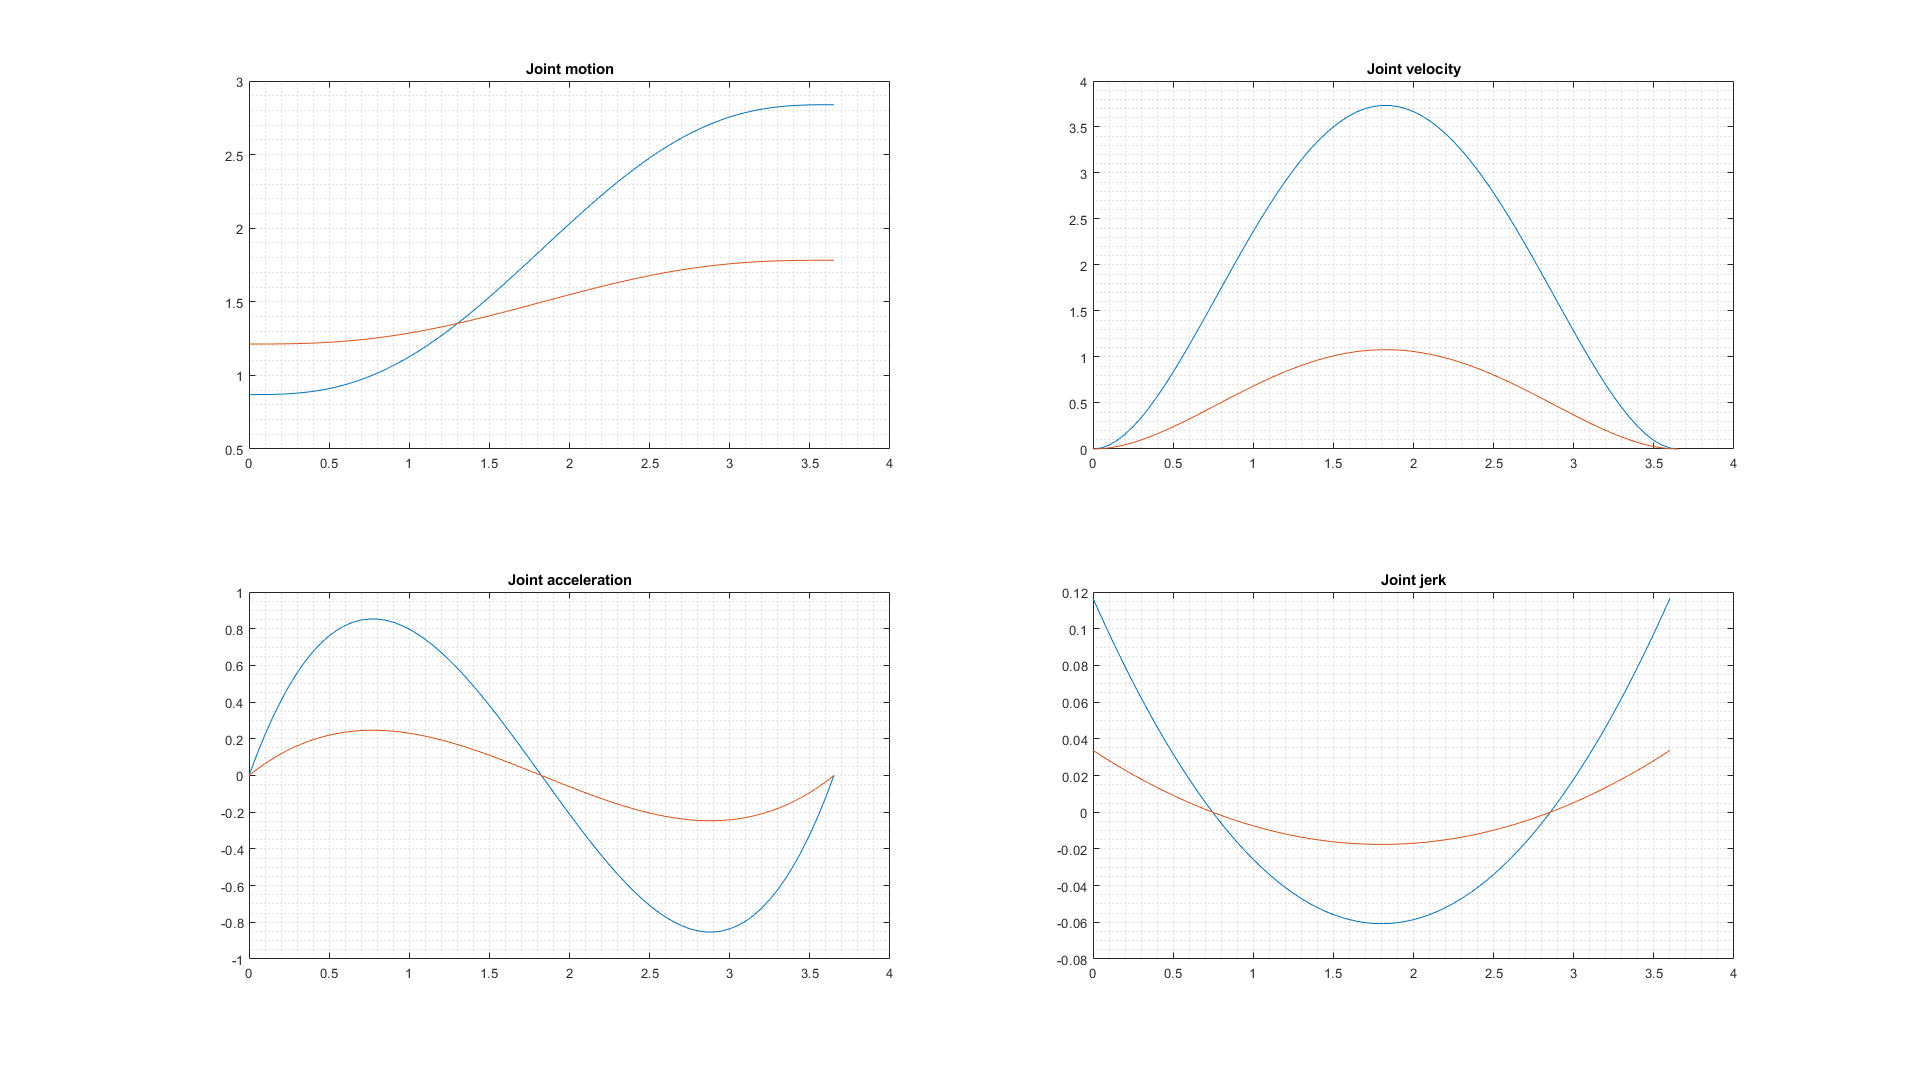

t = [0:0.05:Tstar]';
%[fq fqd fqdd] = mtraj(@poly, qin, qfin, t);
[fq fqd fqdd] = jtraj(qin, qfin , t);

fig1 = figure(1);

subplot(2,2,1,'XGrid','on');
plot(t,fq);
title('Joint motion')

subplot(2,2,2)
plot(t,fqd*Tstar);
title('Joint velocity')

subplot(2,2,3)
plot(t,fqdd);
title('Joint acceleration')

subplot(2,2,4)
plot(t(1:end-1),diff(fqdd));
title('Joint jerk')
set(fig1, 'Units', 'Normalized', 'OuterPosition', [0 0 1 1]);
set(get(fig1 ,'children'),'XMinorGrid','on','YMinorGrid','on')

close all
figure(2)
%twolink = SerialLink(L, 'name', 'two link')
r = SerialLink([0 0 l(1) 0;
                0 0 l(2) 0], 'name', 'two link')

 
r = 
 
two link:: 2 axis, RR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|        0.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


pl = 2.5 %plotlimit

pl = 2.5000

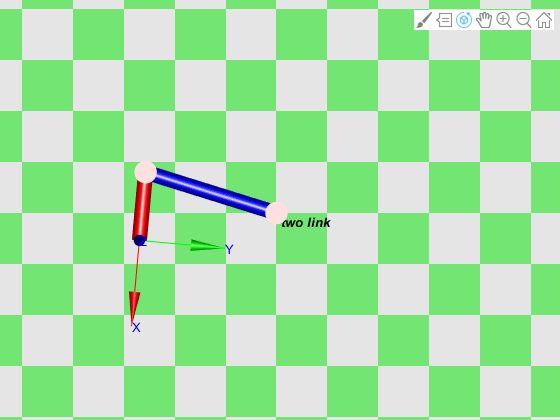

r.plot(fq,'view', 'top','workspace',[-pl,pl,-pl,pl,-2,1])